**VSI power circuit**

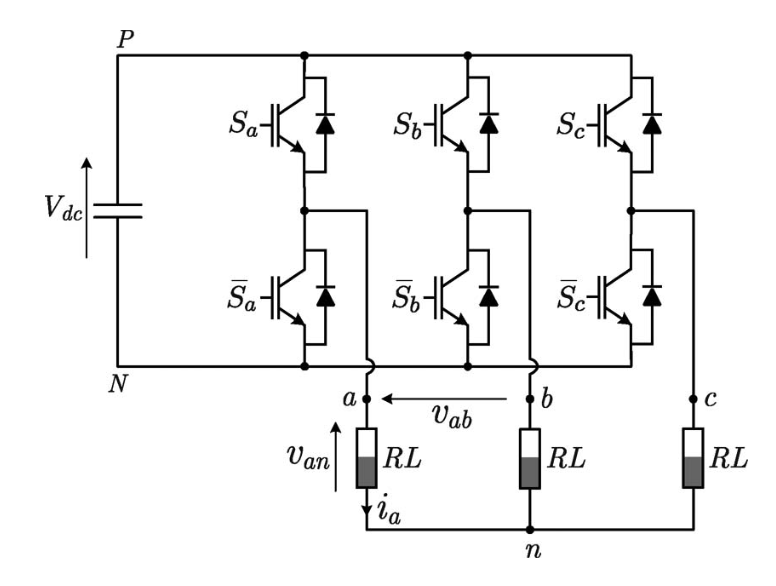

Figure from  [1]: S. Kouro, P. Cortés, R. Vargas, U. Ammann, and J. Rodríguez, “Model predictive control – a simple and powerful method to control power converters,” IEEE Transactions on Industrial Electronics, vol. 56, no. 6, pp. 1826–1838, June 2009. 

The following model followed [2]: Long-Horizon Finite-Control-Set Model Predictive Control with Non-Recursive Sphere Decoding on an FPGA,  Tinus Dorfling, Toit Mouton, Tobias Geyer, Petros Karamanakos.

clc, clear all, close all

Ts = 1/1000; % secCALIBRAonds
Vd = 60; % voltage
Vdc = Vd;
R = 22.5;  %127 % ohms
L = 0.10 ; % henry
x_ref = [0.5 0.5]' ;

%**************************************************************************
%                       INIT SYSTEM PARAMETERS
%**************************************************************************
% transformada clark
K = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2] ;

I_2 = eye(2);

% state matrix
F = - R/L * I_2;
G = (Vd/(2*L)) * K;
A = expm(F*Ts); % matrix exponential
B = -F^(-1) * (I_2 - A) * G;

lambda = 0.01; % switch
lambda_i = 10 ; % current


uk=[0 0 0]';

switch_state = [
    0 0 0;
    0 0 1;
    0 1 0;
    0 1 1;
    1 0 0;
    1 1 0;
    1 0 1;
    1 1 1;
];

n = (size(switch_state));
n = n(1);
np=1;


%**************************************************************************
%**************************************************************************
%**************************************************************************
%**************************************************************************
%
% POSSIBILITIES
%
%**************************************************************************
% Condicao 0 inicial
x0 = [0 ; 0];
i_alfa = x0(1); i_beta = x0(2);
u0 = [0 ; 0 ; 0];
i_alfabeta = x0;
%**************************************************************************

k_test = 30;
x = cell(k_test,1);
x{1} = x0;
u = cell(k_test,1);
x{2} = x0;

u{1} = u0;
index_min_all = zeros(k_test-1,1);
g_i_all = zeros(n,1)

g_i_all =      0
     0
     0
     0
     0
     0
     0
     0


for k = 2 : k_test
        g=zeros(n,1);

        for possibilidade=1:n
            disp ("A * x{k} ")
            disp(A * x{k} )
            disp ("B * u{k} ")
            disp(B * switch_state(possibilidade,1:end)'  )
            x_p = A * x{k} + B * switch_state(possibilidade,1:end)' ;

            g_u = norm([u{k-1} - switch_state(possibilidade,1:end)']) ;

            g_i = norm(x_ref - x_p) ;

            g(possibilidade) =  lambda * g_u + lambda_i * g_i ;
        end

        index_min_all(k) = find(g==min(g)) ;
        gi_all(k) = g(find(g==min(g))) ;
        u{k} = switch_state( find(g==min(g)) , 1:end )' ;
        x{k+1} = A * x{k} + B * u{k};
        disp(x{k})

end

A * x{k} 


     0
     0



B * u{k} 


     0
     0



A * x{k} 


     0
     0



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


     0
     0



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


     0
     0



B * u{k} 


   -0.1791
         0



A * x{k} 


     0
     0



B * u{k} 


    0.1791
         0



A * x{k} 


     0
     0



B * u{k} 


    0.0895
    0.1551



A * x{k} 


     0
     0



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


     0
     0



B * u{k} 


     0
     0



     0
     0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


     0
     0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.1791
         0



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.0715
    0.1239



B * u{k} 


     0
     0



    0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


     0
     0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.1791
         0



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.1286
    0.2227



B * u{k} 


     0
     0



    0.1611
    0.2790



A * x{k} 


    0.1742
    0.3017



B * u{k} 


     0
     0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.1791
         0



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.1742
    0.3017



B * u{k} 


     0
     0



    0.2182
    0.3779



A * x{k} 


    0.2106
    0.3648



B * u{k} 


     0
     0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.1791
         0



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.2106
    0.3648



B * u{k} 


     0
     0



    0.2637
    0.4568



A * x{k} 


    0.3112
    0.2913



B * u{k} 


     0
     0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3112
    0.2913



B * u{k} 


     0
     0



    0.3897
    0.3648



A * x{k} 


    0.3200
    0.3564



B * u{k} 


     0
     0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3200
    0.3564



B * u{k} 


     0
     0



    0.4007
    0.4464



A * x{k} 


    0.3270
    0.4085



B * u{k} 


     0
     0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3270
    0.4085



B * u{k} 


     0
     0



    0.4095
    0.5115



A * x{k} 


    0.4041
    0.3262



B * u{k} 


     0
     0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4041
    0.3262



B * u{k} 


     0
     0



    0.5061
    0.4085



A * x{k} 


    0.3942
    0.3843



B * u{k} 


     0
     0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3942
    0.3843



B * u{k} 


     0
     0



    0.4937
    0.4813



A * x{k} 


    0.3863
    0.4307



B * u{k} 


     0
     0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3863
    0.4307



B * u{k} 


     0
     0



    0.4838
    0.5394



A * x{k} 


    0.3800
    0.4678



B * u{k} 


     0
     0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3800
    0.4678



B * u{k} 


     0
     0



    0.4758
    0.5858



A * x{k} 


    0.4464
    0.3735



B * u{k} 


     0
     0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4464
    0.3735



B * u{k} 


     0
     0



    0.5591
    0.4678



A * x{k} 


    0.4280
    0.4221



B * u{k} 


     0
     0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4280
    0.4221



B * u{k} 


     0
     0



    0.5360
    0.5286



A * x{k} 


    0.4133
    0.4609



B * u{k} 


     0
     0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4133
    0.4609



B * u{k} 


     0
     0



    0.5175
    0.5772



A * x{k} 


    0.3300
    0.3681



B * u{k} 


     0
     0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3300
    0.3681



B * u{k} 


     0
     0



    0.4133
    0.4609



A * x{k} 


    0.3350
    0.4178



B * u{k} 


     0
     0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3350
    0.4178



B * u{k} 


     0
     0



    0.4195
    0.5232



A * x{k} 


    0.4105
    0.3336



B * u{k} 


     0
     0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4105
    0.3336



B * u{k} 


     0
     0



    0.5141
    0.4178



A * x{k} 


    0.3993
    0.3902



B * u{k} 


     0
     0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3993
    0.3902



B * u{k} 


     0
     0



    0.5001
    0.4887



A * x{k} 


    0.3904
    0.4355



B * u{k} 


     0
     0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3904
    0.4355



B * u{k} 


     0
     0



    0.4889
    0.5453



A * x{k} 


    0.3832
    0.4716



B * u{k} 


     0
     0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3832
    0.4716



B * u{k} 


     0
     0



    0.4799
    0.5906



A * x{k} 


    0.4490
    0.3766



B * u{k} 


     0
     0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4490
    0.3766



B * u{k} 


     0
     0



    0.5623
    0.4716



A * x{k} 


    0.4301
    0.4245



B * u{k} 


     0
     0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4301
    0.4245



B * u{k} 


     0
     0



    0.5386
    0.5317



A * x{k} 


    0.4149
    0.4629



B * u{k} 


     0
     0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4149
    0.4629



B * u{k} 


     0
     0



    0.5196
    0.5796



A * x{k} 


    0.3313
    0.3696



B * u{k} 


     0
     0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3313
    0.3696



B * u{k} 


     0
     0



    0.4149
    0.4629



A * x{k} 


    0.3361
    0.4190



B * u{k} 


     0
     0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3361
    0.4190



B * u{k} 


     0
     0



    0.4209
    0.5247



A * x{k} 


    0.4114
    0.3346



B * u{k} 


     0
     0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4114
    0.3346



B * u{k} 


     0
     0



    0.5152
    0.4190



A * x{k} 


    0.4000
    0.3910



B * u{k} 


     0
     0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.1791
         0



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.4000
    0.3910



B * u{k} 


     0
     0



    0.5009
    0.4897



A * x{k} 


    0.3909
    0.4361



B * u{k} 


     0
     0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.0895
   -0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.0895
    0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


   -0.1791
         0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.1791
         0



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.0895
    0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


    0.0895
   -0.1551



A * x{k} 


    0.3909
    0.4361



B * u{k} 


     0
     0



    0.4895
    0.5461




i_alfa = zeros(k_test, 1);
i_beta = zeros(k_test, 1);
i_a_all = zeros(k_test, 1);
i_b_all = zeros(k_test, 1);
i_c_all = zeros(k_test, 1);
i_abc=  zeros(k_test, 3);
ua = zeros(k_test, 1);
ub = zeros(k_test, 1);
uc = zeros(k_test, 1);
vf_all= zeros(k_test, 1);
i_all = cell2mat(x);
u_all = cell2mat(u);
size_i_all = size(i_all);
size_i_all = size_i_all(1);

cont = 1;
for i = 3:2:size_i_all
    i_alfa(cont) = i_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 4:2:size_i_all
    i_beta(cont) = i_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    ik = K * [1, 0 ; 0, 1; -1, -1] * [i_alfa(i); i_beta(i)]
    ia = ik(1)
    ib = ik(2)
    ic= ia-ib;

    i_a_all(i) = ia ;
    i_b_all(i) = ib ;
    i_c_all(i) = ic;
    i_abc(i,1:3) = [ia ; ib ; ic ];
end

ik =      0
     0


ia = 0

ib = 0

ik =     0.0895
    0.2308


ia = 0.0895

ib = 0.2308

ik =     0.1611
    0.4151


ia = 0.1611

ib = 0.4151

ik =     0.2182
    0.5623


ia = 0.2182

ib = 0.5623

ik =     0.2637
    0.6798


ia = 0.2637

ib = 0.6798

ik =     0.3897
    0.6462


ia = 0.3897

ib = 0.6462

ik =     0.4007
    0.7468


ia = 0.4007

ib = 0.7468

ik =     0.4095
    0.8271


ia = 0.4095

ib = 0.8271

ik =     0.5061
    0.7639


ia = 0.5061

ib = 0.7639

ik =     0.4937
    0.8408


ia = 0.4937

ib = 0.8408

ik =     0.4838
    0.9022


ia = 0.4838

ib = 0.9022

ik =     0.4758
    0.9512


ia = 0.4758

ib = 0.9512

ik =     0.5591
    0.8629


ia = 0.5591

ib = 0.8629

ik =     0.5360
    0.9199


ia = 0.5360

ib = 0.9199

ik =     0.5175
    0.9653


ia = 0.5175

ib = 0.9653

ik =     0.4133
    0.7708


ia = 0.4133

ib = 0.7708

ik =     0.4195
    0.8463


ia = 0.4195

ib = 0.8463

ik =     0.5141
    0.7792


ia = 0.5141

ib = 0.7792

ik =     0.5001
    0.8530


ia = 0.5001

ib = 0.8530

ik =     0.4889
    0.9119


ia = 0.4889

ib = 0.9119

ik =     0.4799
    0.9590


ia = 0.4799

ib = 0.9590

ik =     0.5623
    0.8692


ia = 0.5623

ib = 0.8692

ik =     0.5386
    0.9248


ia = 0.5386

ib = 0.9248

ik =     0.5196
    0.9693


ia = 0.5196

ib = 0.9693

ik =     0.4149
    0.7740


ia = 0.4149

ib = 0.7740

ik =     0.4209
    0.8489


ia = 0.4209

ib = 0.8489

ik =     0.5152
    0.7812


ia = 0.5152

ib = 0.7812

ik =     0.5009
    0.8546


ia = 0.5009

ib = 0.8546

ik =     0.4895
    0.9132


ia = 0.4895

ib = 0.9132

ik =     0.4805
    0.9600


ia = 0.4805

ib = 0.9600

cont = 1;
for i = 1:3:length(u_all)
    ua(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 2:3:length(u_all)
    ub(cont) = u_all(i);
    cont = cont + 1;
end
cont = 1;
for i = 3:3:length(u_all)
    uc(i) = u_all(i);
    cont = cont + 1;
end
for i = 1:k_test
    vf_all(i) = 2/3 * (Vdc/2 * ua(i) * exp(j*0) + Vdc/2 * ub(i) * exp(j*2/3) + Vdc/2 * uc(i) * exp(j*4*pi/3) );
end




% plot control
figure
x=5;
colors = {'r', 'g', 'b', 'm', 'c', 'y', 'k', 'r', 'g'};
hold on;
xlabel('k'), ylabel(' I [A] ');
legend('x_1(t)', 'x_2(t)')

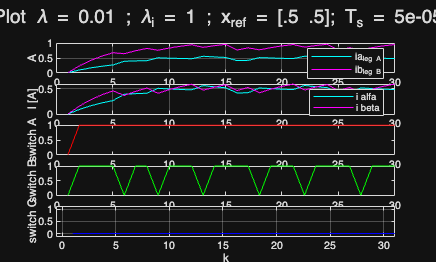

sgtitle('Plot \lambda = 0.01 ; \lambda_i = 1 ; x_{ref} = [.5 .5]; T_s = 5e-05');

subplot(x,1,1);
plot(i_a_all, colors{5}); hold on;
plot(i_b_all, colors{4}); hold on;
legend('ia_{leg A}', 'ib_{leg B} ')
ylabel('A');
grid on;

subplot(x,1,2);
plot(i_alfa, colors{5});hold on;
plot(i_beta, colors{4});hold on;

legend('i alfa ', 'i beta ')
xlabel('k'), ylabel(' I [A] ')
grid on;

subplot(x,1,3);
plot(ua, colors{1}); hold on;
xlabel('k'), ylabel(' switch A ')

subplot(x,1,4);
plot(ub, colors{2}); hold on;
xlabel('k'), ylabel(' switch B ')

subplot(x,1,5);
plot(uc, colors{3}); hold on;
xlabel('k'), ylabel(' switch C ')

axis([-0.5 length(ua)+1 -0.1 1.1]);
grid on;

**2L VSI GPC**

A modulacao por pulsos é uma alternativa para implementar uma atuacao proporcional usando um atuador tipo liga-desliga. Caso a frequencia usada para ligar e desligar o atuador seja muito maior que o inverso do período de tempo médio das dinâmicas do sistema, entao, potemos considerar que o sistema recebe uma atuacao dada pelo valor médio do sinal de tensao enviado. O conceito associado ao controle Proporcional-Integral é o seguinte: a ação de controle PI é composta por duas parcelas, uma delas proporcional ao erro de seguinmento e a outra à integral do erro de seguimento. O principal objetivo é garantir que a variável de processo se mantenha, em regime permanente, emum valor de referência desejado.

Para muitas análises, podemos **simplificar o motor** representando cada fase por um circuito **resistivo-indutivo (R–L) **alimentado por uma fonte senoidal.


$$v\left(t\right)=\mathrm{Ri}\left(t\right)+\frac{\mathrm{Ldi}\left(t\right)}{\mathrm{dt}}$$


Model RLC from [3] Diego Rojas, Marco Rivera, Sergio Toledo, and Patrick Wheeler. Predictive control techniques applied to a 2L-VSI.

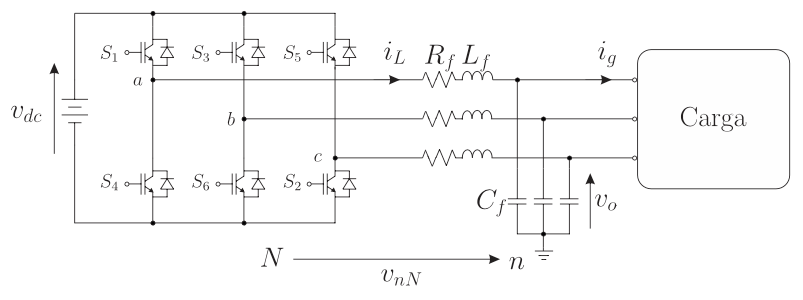

clc
%% LC Filter State-Space Model for GPC
% This script implements the continuous and discrete-time models
% for an LC filter with state-space representation
% transformada clark
K = 2/3 * [1 -1/2 -1/2; 0 sqrt(3)/2 -sqrt(3)/2] ;

I_2 = eye(2);

%**************************************************************************
%                       INIT SYSTEM PARAMETERS
%**************************************************************************

% hardware lab measurements
Ts = 1e-2;  % Sampling time
Vd = 100; VDC = Vd;Vdc = Vd;  % voltage
R = 3.5;  %3.5 % ohms
L = 0.0025 ; % henry

% Example parameters for a typical LC filter
Rf = 0.1;        % Resistance [Ω]
Lf = 1e-3;       % Inductance [mH]
Cf = 10e-6;      % Capacitance [μF]
Ts_filter = 100e-6;   %  [100 μs = 10 kHz]

%% Continuous-Time State-Space Matrices
A1 = [-Rf/Lf,  -1/Lf;
       1/Cf,    0   ]

A1 = 1.0e+05 *

   -0.0010   -0.0100
    1.0000         0


Ad = expm(A1 * Ts);


B = [1/Lf,     0;
         0,    -1/Cf];

B1 = [Vdc/Lf;  0];
C1 = [1 0];


D1 = 0;
[Bc, Ac] = ss2tf(A1, B1, C1, D1);
Tz = c2d(tf(Bc, Ac), Ts) % Discretized


Tz =
 
     -3.078 z + 3.078
  ----------------------
  z^2 - 1.045 z + 0.3679
 
Sample time: 0.01 seconds
Discrete-time transfer function.


A = cell2mat(Tz.den); %   A(z-¹)
B = cell2mat(Tz.num); %   B(z-¹)

C = [1 0];


D = 0;
Bq = [0.001]; % numerador do modelo da perturbação do processo

% % state-space system
% sysc = ss(A, B, C, D);
% 
% sysd = ss(A, B, C, D, Ts);
% A = [sysd.A]


%[Ad,Bd] = c2dm(sysc.A,sysc.B,sysc.C,[0 0],Ts,'zoh')

i_L_k = 5;       % 5 A
v_alpha_k = 230; % 230 V
v_o_k = 220;     % 220 V
i_g_k = 4.5;     % 4.5 A


d=0; % atraso em relação à manipulada
dq = 0; % atraso em relação à perturbação

nb = size(B,2)-1; % ordem do polinômio B
na = size(A,2)-1; % ordem do polinômio A
nbq = size(Bq,2)-1; % ordem do polinômio Bq


%% parâmetros de ajuste

N1 = 1; %horizonte de predição inicial
N2 = 30; % horizonte de predição final
N = N2-N1+1; % horizonte de predição
Nu = 3; % horizonte de controle
Nq = 0; % horizonte da ação antecipativa

delta = 1; % ponderação do erro futuro
lambda = 1; % ponderação do esforço de controle


%% montagem das matrizes
Btil = conv(B,[zeros(1,d) 1]); % incorporação do atraso no numerador B
Bqtil = conv(Bq,[zeros(1,dq) 1]); % incorporação do atraso no numerador Bq


G = zeros(N,N); % matriz dinâmica G
H = zeros(N,nb+d); % matriz dos incrementos passados de controle 
Gq = zeros(N,N-1); % matris dos incrementos da perturbação futura
Hq = zeros(N,nbq+dq); % matriz dos incrementos passados da perturbação 

[E,F] = diofantina(conv2(A,[1 -1]),N1,N2); % obtenção dos polinômios Ej, Fj

for i=N1:N2
    EjB = conv2(E(i-N1+1,1:i),Btil);
    EjBq = conv2(E(i-N1+1,1:i),Bqtil);
    
    G(i-N1+1,1:i) = EjB(i:-1:1);    
    H(i-N1+1,:) = EjB(i+1:end);

    Gq(i-N1+1,1:i) = EjBq(i:-1:1);    
    Hq(i-N1+1,:) = EjBq(i+1:end);
    
end
G = G(:,1:Nu);
Gq = Gq(:,1:Nq);


G,F,H,Gq,Hq

G =          0         0         0
   -3.0778         0         0
   -3.2172   -3.0778         0
   -2.2306   -3.2172   -3.0778
   -1.1480   -2.2306   -3.2172
   -0.3794   -1.1480   -2.2306
    0.0257   -0.3794   -1.1480
    0.1665    0.0257   -0.3794
    0.1646    0.1665    0.0257
    0.1108    0.1646    0.1665
    0.0552    0.1108    0.1646
    0.0170    0.0552    0.1108
   -0.0026    0.0170    0.0552
   -0.0089   -0.0026    0.0170
   -0.0084   -0.0089   -0.0026


F =     2.0453   -1.4132    0.3679
    2.7700   -2.5224    0.7524
    3.1430   -3.1620    1.0190
    3.2663   -3.4225    1.1562
    3.2579   -3.4595    1.2016
    3.2038   -3.4024    1.1985
    3.1504   -3.3290    1.1786
    3.1144   -3.2733    1.1590
    3.0964   -3.2422    1.1457
    3.0909   -3.2300    1.1391
    3.0917   -3.2288    1.1371
    3.0946   -3.2320    1.1374
    3.0974   -3.2358    1.1385
    3.0992   -3.2386    1.1395
    3.1000   -3.2401    1.1401


H =    -3.0778    3.0778
   -3.2172    6.2950
   -2.2306    8.5256
   -1.1480    9.6737
   -0.3794   10.0531
    0.0257   10.0274
    0.1665    9.8609
    0.1646    9.6963
    0.1108    9.5856
    0.0552    9.5303
    0.0170    9.5133
   -0.0026    9.5159
   -0.0089    9.5248
   -0.0084    9.5332
   -0.0055    9.5387



Gq =

  30×0 empty double matrix


Hq =

  30×0 empty double matrix




%% obtenção do ganho irrestrito
Qu = lambda*eye(Nu); % matriz de ponderação dos incrementos de controle
Qe = delta*eye(N);  % matriz de ponderaão dos erros futuros

Kmpc = (G'*Qe*G+Qu)\G'*Qe;

Kmpc1 = Kmpc(1,:);

%% inicialização vetores
nin = 5;
nit = 100 + nin; % número de iterações da simulação

entradas = 0*ones(nit,1); % vetor o sinal de controle
du = zeros(nit,1); % vetor de incrementos de controle

saidas = 0*ones(nit,1); % vetor com as saídas do sistema

perts = zeros(nit,1); % vetor com as perturbações do sistema
perts(nin+50:end) = 0.5;

refs = 0*ones(nit,1); % vetor de referências
refs(nin+10:end) = 1;



%% simulação sem filtro de referência
for k = nin:nit
    %% modelo processo, não mexer
    saidas(k) = -A(2:end)*saidas(k-1:-1:k-na) ...
                  +B*entradas(k-d-1:-1:k-1-nb-d) ...
                  +Bq*perts(k-dq:-1:k-nbq-dq);    
    
    %% -- Controlador GPC 
    %%% referencias
    R = refs(k)*ones(N,1);
    
    %%% cálculo da resposta livre;
    f = F*saidas(k:-1:k-na);
    
    if(~isempty(H))
        f = f+ H*du(k-1:-1:k-nb-d); % parcela dos incrementos de controle
    end
    
    %% Resolve o problema de otimização
    du(k) = Kmpc1*(R-f);
    entradas(k) = entradas(k-1)+du(k);
    
    %%  Current Prediction (Equation 9)
    % PREDICT_CURRENT Predicts inductor current at k+1
    % Equation (9):
    % i_Lαβ(k+1) = (1 - Rf*Ts/Lf)*i_Lαβ(k) - Ts/Lf*(v_αβ(k) - v_oαβ(k))
    % Inputs:
    %   i_L_k - Current at time k [A]
    %   v_alpha_k - Input voltage αβ at time k [V]
    %   v_o_k - Output voltage at time k [V]
    %   Rf, Lf - Filter parameters
    %   Ts - Sampling time [s]
    %
    % Output:
    %   i_L_next - Predicted current at k+1 [A]
end

    
a11 = 1 - Rf*Ts/Lf;
b_coeff = Ts/Lf;

i_L_next = a11 * i_L_k - b_coeff * (v_alpha_k - v_o_k);


% end
% 
% 
% % Predict current
% i_L_next = predict_current(i_L_k, v_alpha_k, v_o_k, Rf, Lf, Ts);
% fprintf('i_L(k) = %.2f A  →  i_L(k+1) = %.4f A\n', i_L_k, i_L_next);
% 
% % Predict voltage
% v_o_next = predict_voltage(v_o_k, i_L_next, i_g_k, Cf, Ts);
% fprintf('v_o(k) = %.2f V  →  v_o(k+1) = %.4f V\n', v_o_k, v_o_next);
% 
% % Using complete state prediction
% x_k = [i_L_k; v_o_k];
% u_k = [v_alpha_k; i_g_k];
% [x_next] = predict_state(x_k, u_k, Rf, Lf, Cf, Ts);
% fprintf('\nUsing state-space model:\n');
% fprintf('x(k+1) = [%.4f; %.4f]\n', x_next(1), x_next(2));
% 
% 
% %% Voltage Prediction (Equation 10)
% function v_o_next = predict_voltage(v_o_k, i_L_next, i_g_k, Cf, Ts)
%     % PREDICT_VOLTAGE Predicts output voltage at k+1
%     %
%     % Equation (10):
%     % v_oαβ(k+1) = v_oαβ(k) + Ts/Cf*i_Lαβ(k+1) - Ts/Cf*i_gαβ(k)
%     %
%     % Inputs:
%     %   v_o_k - Output voltage at time k [V]
%     %   i_L_next - Inductor current at k+1 [A]
%     %   i_g_k - Grid current at time k [A]
%     %   Cf - Filter capacitance [F]
%     %   Ts - Sampling time [s]
%     %
%     % Output:
%     %   v_o_next - Predicted voltage at k+1 [V]
%     
%     b_coeff = Ts/Cf;
%     
%     v_o_next = v_o_k + b_coeff * i_L_next - b_coeff * i_g_k;
% end
% 
% %% Function 5: Complete State Prediction (Equation 11)
%     % PREDICT_STATE Complete state prediction using discrete model
%     %
%     % Equation (11):
%     % [i_Lαβ(k+1)]   [a11  a12] [i_Lαβ(k) ]   [b11  b12] [v_αβ(k) ]
%     % [v_oαβ(k+1)] = [a21  a22] [v_oαβ(k) ] + [b21  b22] [i_gαβ(k)]
%     %
%     % Inputs:
%     %   x_k - State vector at k: [i_Lαβ(k); v_oαβ(k)]
%     %   u_k - Input vector at k: [v_αβ(k); i_gαβ(k)]
%     %   Rf, Lf, Cf - Filter parameters
%     %   Ts - Sampling time [s]
%     %
%     % Outputs:
%     %   x_next - State vector at k+1
%     %   Ad, Bd - Discrete matrices (for reference)
% %     
% %     % Get discrete matrices
% %     [Ad, Bd] = lc_filter_discrete(Rf, Lf, Cf, Ts, 'euler');
% %     
% %     % State prediction
% %     x_next = Ad * x_k + Bd * u_k;
% 
% 
% % GPC Dynamic Matrix
% % fprintf('\n=== GPC Dynamic Matrix ===\n');
% Nu = 2;  % Control horizon
% G = build_gpc_dynamic_matrix(Rf, Lf, Cf, Ts, N, Nu);
% fprintf('G matrix dimensions: %dx%d\n', size(G,1), size(G,2));
% fprintf('G matrix:\n');
% disp(G);


%% plots
t = ((nin:nit)-nin)*Ts;
vx = nin:nit;

cores = gray(3);
cores = cores(1:end-1,:);

tamletra = 12;
tamlinha = 4;
tamfigura= [1 1 1 1];
hf = figure

hf =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [267 191 560 337.0317]
       Units: 'pixels'

  Show all properties


h=subplot(3,1,1)

h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7093 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(t,saidas(vx),'LineWidth',tamlinha,'Color',cores(1,:))
hold on
plot(t,refs(vx),'--','LineWidth',tamlinha,'Color',cores(2,:))
ylim([0 1.5])
h.YTick = [0 0.5 1 1.5];
hl = legend('Caso 1','Referência','Location','NorthEast')

hl =   Legend (Caso 1, Referência) with properties:

         String: {'Caso 1'  'Referência'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.7113 0.8325 0.1744 0.0766]
          Units: 'normalized'

  Show all properties


ylabel('Controlada','FontSize', tamletra)
set(h, 'FontSize', tamletra);
grid on

h = subplot(3,1,2)

h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(t,entradas(vx),'LineWidth',tamlinha,'Color',cores(1,:))
h.YTick = [-2 -1 0 1 2]

h =   Axes with properties:

             XLim: [0 1]
             YLim: [-10 0]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


ylim([-2.5 2])

ylabel('Manipulada','FontSize', tamletra)
grid on

set(h, 'FontSize', tamletra);

h = subplot(3,1,3)

h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.2157]
            Units: 'normalized'

  Show all properties


plot(t,du(vx),'LineWidth',tamlinha,'Color',cores(1,:))
% h.YTick = [-2 -1 0 1 2]
% ylim([-2.5 2])
grid on
ylabel('\Delta u','FontSize', tamletra)
xlabel('Tempo (amostras)','FontSize', tamletra)

set(h, 'FontSize', tamletra);

hf.Position = tamfigura;
hl.Position = [0.6952 0.6683 0.2054 0.1242];

please ignore

work in progresss

% %**************************************************************************
% %                       INIT SYSTEM PARAMETERS
% %**************************************************************************
% Ts = 1e-2; % seconds
% Vd = 100; % voltage
% VDC = Vd;
% Vdc = Vd;  
% R = 3.5;  %3.5 % ohms
% L = 0.0025 ; % henry
% n=7; % combinations
% 
%     
% a=exp(j*pi*2/3);
% switch_position = [ % ordered
%     1 0 0;  % + 0 0
%     1 1 0;  % + + 0
%     0 1 0;  % 0 + 0
%     0 0 1;  % 0 0 +
%     0 1 1;  % 0 + +
%     1 0 1;  % + 0 +
%     1 1 1;  % + + +
%     ];
% 
% for i = 1:n
%     ua = switch_position(i,1);
%     ub = switch_position(i,2);
%     uc = switch_position(i,3);
% 
%     SA(i) = ua;
%     SB(i) = ub;
%     SC(i) = uc;
% 
%     u(i,:) = [ua ub uc]';
%     
%     %phase output voltages
%     va = Vd/2 * ua;
%     vb = Vd/2 * ub;
%     vc = Vd/2 * uc;
%     v(i,:) = [va vb vc];
% 
%     %line-to-line voltages
%     vab = va-vb;
%     vbc = vb-vc;
%     vca = vc-va;
%     
%     v_ab(i)=((ua-ub)*Vd);
%     v_bc(i)=((ub-uc)*Vd);
%     v_ca(i)=((uc-ua)*Vd);
% 
%     vl(i,:) = [vab vbc vca];
% 
%     % final voltages for all combinations
%     Vs(i) = 2/3 * (Vdc/2 * ua * a + Vdc/2 * ub * a + Vdc/2 * uc * a );
% 
% end
% 
% 
% G = 1/(L*s+R)
% i_sp(S_i) = L*i+s(t_k) + Ts*v_i(t_k1)
% 
% v_i(t_k1) = 2/3*Vdc*(S_i*[1 a a^2]')
% 
% %cost function
% g= x-xp
% g1 = g^2

3L VSI

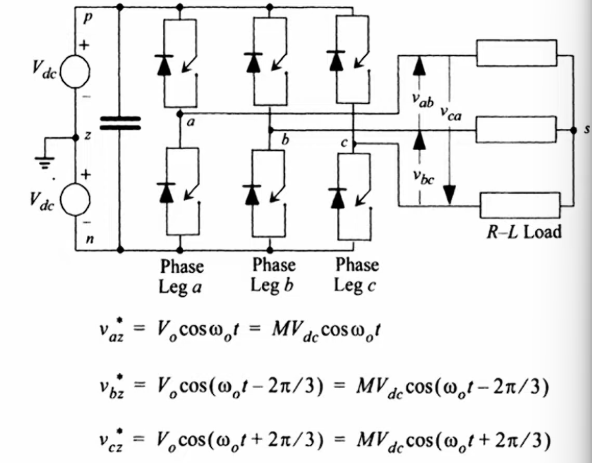

Diofantina

%% Função para o cálculo da equação diofantina

function [E,F] = diofantina(A,N1,N2)

    % Cálculo dos polinômios E(z) e F(z)
    
    nA = size(A,2); % ordem de A(z)
    
    % Cálculo de F(z)
    f(1,:) = [1 zeros(1,nA-2)]; % inicializa F
    
    for j=1:N2
        for i=1:nA-2
            f(j+1,i) = f(j,i+1)-f(j,1)*A(i+1);
        end
        f(j+1,nA-1) = -f(j,1)*A(nA);
    end
    
    F = f(1+N1:1+N2,:);
    
    % Cálculo de E(z)
    E = zeros(N2);
    e(1) = 1;
    E(1,1) = e(1);
    
    for i=2:N2
        e(i) = f(i,1);
        E(i,1:i) = e;
    end
    
    E = E(N1:N2,:);


end

Diofantina com C(z-1)

%% Função para o cálculo da equação diofantina

function [E,F] = diofantinaC(A,C,N1,N2)
    
    % Cálculo dos polinômios E(z) e F(z)
    % delta = [1 -1]; % delta = 1-z^{-1}
    % AD = conv(A,delta) ; % AD = A(z)*Delta(z)
    
    nA1 = size(A,2); % numero de elemnetos de A(z)
    nC = size(C,2); % numero de elementos de C(z)
    
    
    %%% calculo da ordem máxima do polinômio F
    nF1 = max(nC,N1-1+nA1)-N1;
    nF2 = max(nC,N2-1+nA1)-N2;
    nF = max(nF1,nF2);
    
    % Cálculo de F(z)
    
    if(nC>nA1)
        A = [A zeros(1,nC-nA1)];
        nA = size(A,2);
    
    else
        nA = nA1;
    end
    
    f(1,:) = [C zeros(1,nA-nC)]; % inicializa F
    
    
    
    for j=1:N2
        for i=1:nA-1
            f(j+1,i) = f(j,i+1)-f(j,1)*A(i+1);
        end
    %     f(j+1,nA-1) = -f(j,1)*A(nA);
    end
    
    F = f(1+N1:1+N2,1:nF);
    
    
    
    % Cálculo de E(z)
    E = zeros(N2);
    e(1) = C(1);
    E(1,1) = e(1);
    
    for i=2:N2
        e(i) = f(i,1);
        E(i,1:i) = e;
    end
    
    E = E(N1:N2,:);

end
